close all
clear variables

% Load the flower images into a dataset

flowersDataset = fullfile("17flowers/");

% Images are stored in a folder with their label type
imds = imageDatastore(flowersDataset, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

numTrainFiles = 80 * 0.8;
[trainingSet,validationSet] = splitEachLabel(imds,numTrainFiles,'randomized');

countEachLabel(trainingSet)

ans = 17×2 table
    Label    Count
    _____    _____

     1        64  
     10       64  
     11       64  
     12       64  
     13       64  
     14       64  
     15       64  
     16       64  
     17       64  
     2        64  
     3        64  
     4        64  
     5        64  
     6        64  
     7        64  
     8        64  


countEachLabel(validationSet)

ans = 17×2 table
    Label    Count
    _____    _____

     1        16  
     10       16  
     11       16  
     12       16  
     13       16  
     14       16  
     15       16  
     16       16  
     17       16  
     2        16  
     3        16  
     4        16  
     5        16  
     6        16  
     7        16  
     8        16  



% figure;
% imshow(trainingSet.Files{102});
% [hog_2x2, vis2x2] = extractHOGFeatures(readimage(trainingSet, 106),'CellSize',[2 2]);
% title('Example images')

trainingSet.ReadSize = 6;
validationSet.ReadSize = 6;

resizeFcn = @(x, info) [imresize(x, [256,256]), info];
trainingSet = transform(trainingSet, @imageAug, 'IncludeInfo',true);
validationSet = transform(validationSet, @imageAug, 'IncludeInfo',true);

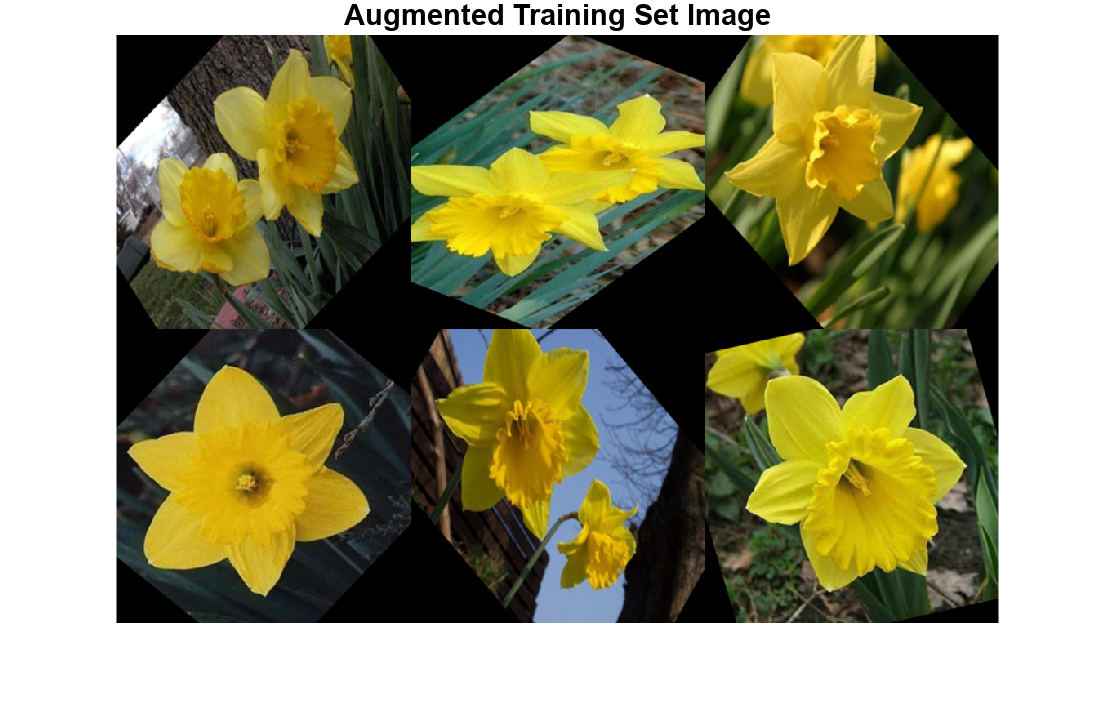

figure;
ims = preview(trainingSet);
ims = ims(:,1);
montage(ims(:));
title("Augmented Training Set Image");

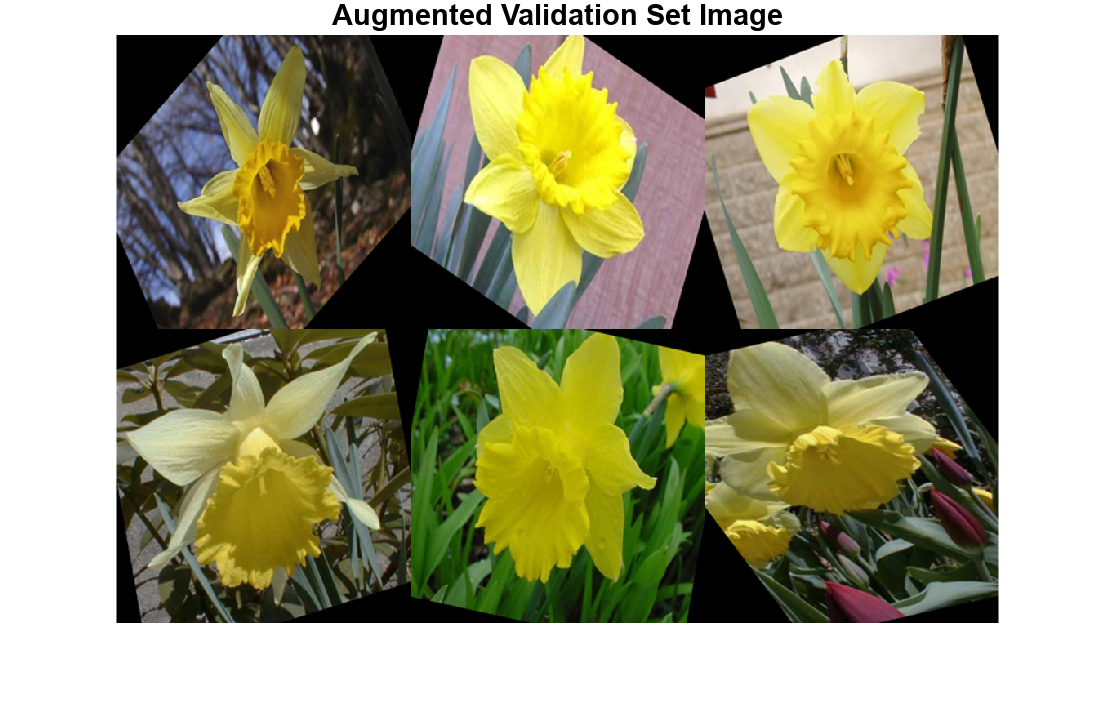


figure;
ims = preview(validationSet);
ims = ims(:,1);
montage(ims(:));
title("Augmented Validation Set Image");


inputSize = [256 256 3];
numClasses = 17;

layers = [
    imageInputLayer(inputSize)

    convolution2dLayer(5,64)
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'stride', 2)

    convolution2dLayer(5,128)
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'stride', 2)

    convolution2dLayer(5,256)
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'stride', 2)

    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer
    ];

options = trainingOptions('adam', ...
    'MiniBatchSize',64,...
    'MaxEpochs',15, ...
    'InitialLearnRate',0.001,...
    'ValidationData',validationSet, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress',...
    'ExecutionEnvironment','multi-gpu');
gpuDevice(1)

ans =   CUDADevice with properties:

                      Name: 'NVIDIA GeForce RTX 3060 Laptop GPU'
                     Index: 1
         ComputeCapability: '8.6'
            SupportsDouble: 1
             DriverVersion: 12
            ToolkitVersion: 11.2000
        MaxThreadsPerBlock: 1024
          MaxShmemPerBlock: 49152 (49.15 KB)
        MaxThreadBlockSize: [1024 1024 64]
               MaxGridSize: [2.1475e+09 65535 65535]
                 SIMDWidth: 32
               TotalMemory: 6441926656 (6.44 GB)
           AvailableMemory: 5029294080 (5.03 GB)
       MultiprocessorCount: 30
              ClockRateKHz: 1282000
               ComputeMode: 'Default'
      GPUOverlapsTransfers: 1
    KernelExecutionTimeout: 1
          CanMapHostMemory: 1
           DeviceSupported: 1
           DeviceAvailable: 1
            DeviceSelected: 1


reset(gpuDevice(1))

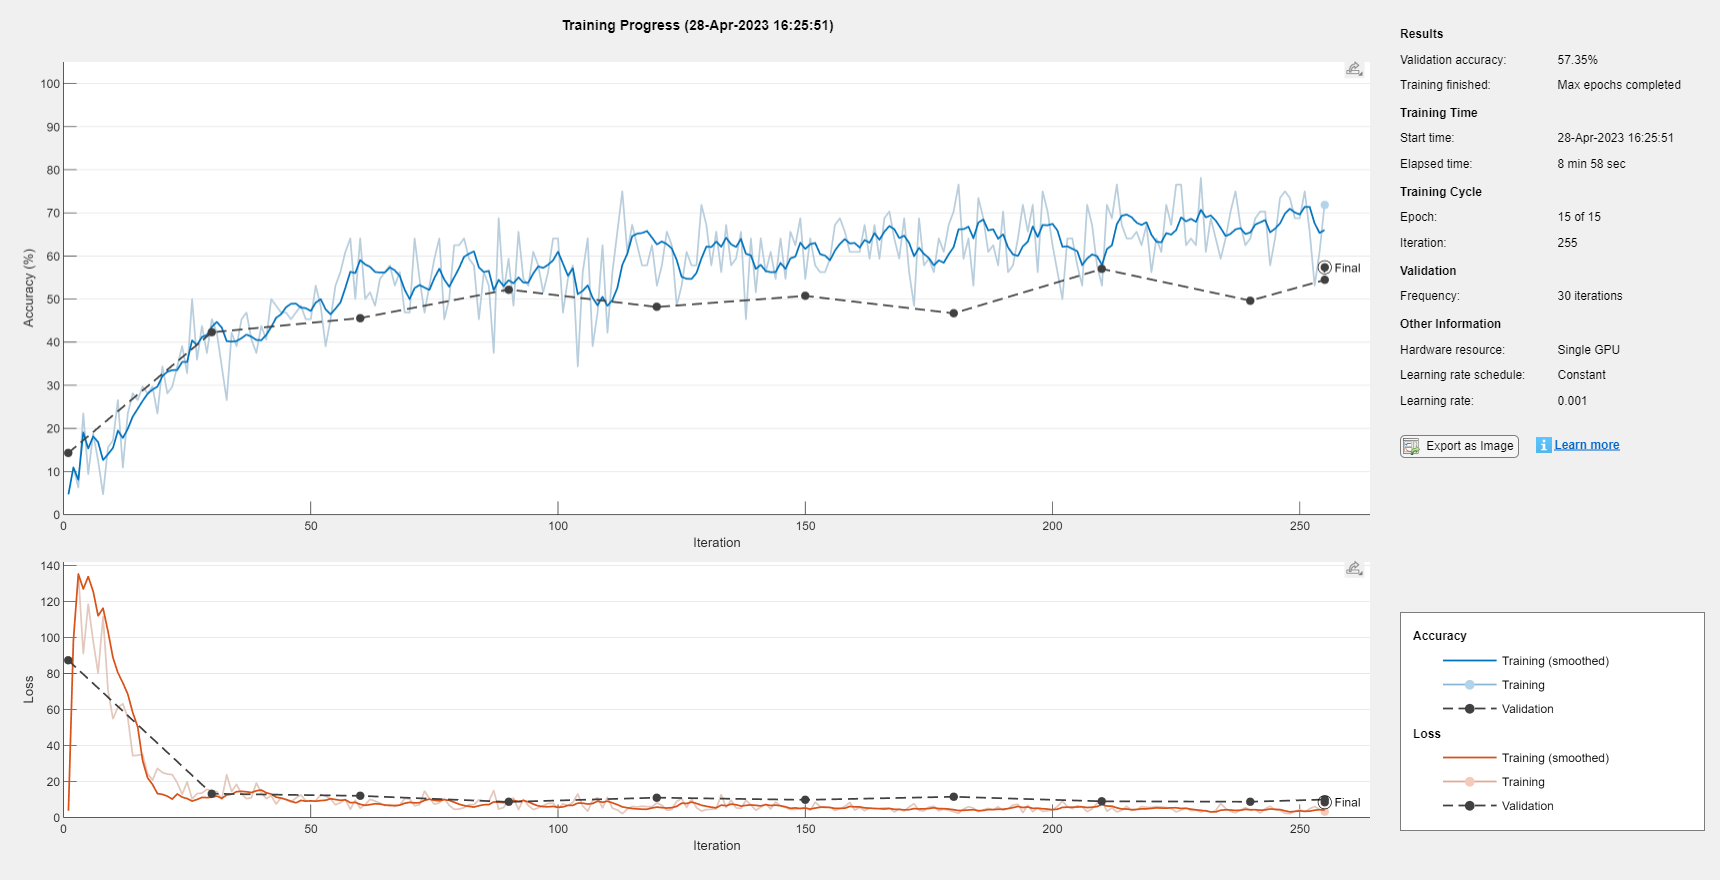

classifier = trainNetwork(trainingSet, layers,options);

save('classnet.mat', 'classifier')

% deepNetworkDesigner(classifier);

predictedLabels = predict(classifier, validationSet, 'ReturnCategorical', true);

confMat = confusionmat(validationSet.UnderlyingDatastores{1}.Labels, predictedLabels);
helperDisplayConfusionMatrix(confMat)

digit  | 0        1        2        3        4        5        6        7        8        9        10       11       12       13       14       15       16       
------------------------------------------------------------------------------------------------------------------------------------------------------------------
     1 | 0.00     0.00     0.00     0.56     0.00     0.00     0.00     0.00     0.00     0.00     0.00     0.00     0.00     0.12     0.00     0.31     0.00     
     2 | 0.06     0.81     0.00     0.12     0.00     0.00     0.00     0.00     0.00     0.00     0.00     0.00     0.00     0.00     0.00     0.00     0.00     
     3 | 0.00     0.00     0.62     0.06     0.00     0.00     0.00     0.06     0.06     0.00     0.00     0.00     0.00     0.12     0.00     0.06     0.00     
     4 | 0.00     0.00     0.00     0.88     0.00     0.00     0.00     0.00     0.00     0.00     0.00     0.00     0.00     0.00     0.00     0.06     0.06     
     5 | 0.00     0.00

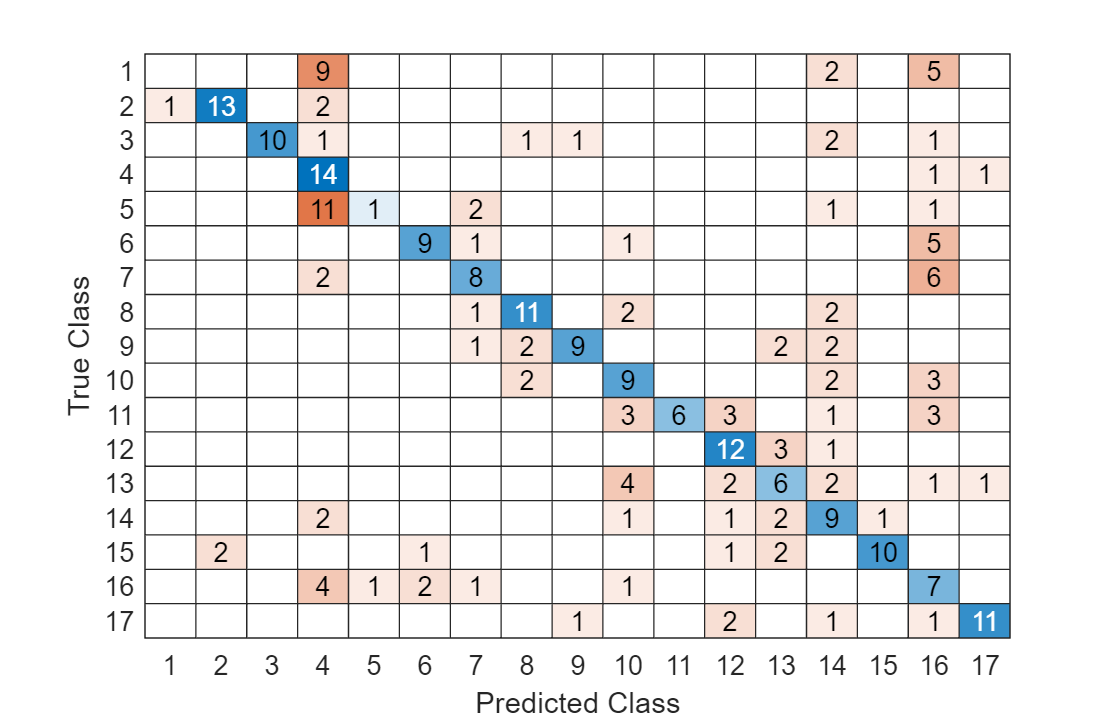

confusionchart(confMat)


accuracy = mean(predictedLabels == validationSet.UnderlyingDatastores{1}.Labels)

accuracy = 0.5331

function helperDisplayConfusionMatrix(confMat)
% Display the confusion matrix in a formatted table.

% Convert confusion matrix into percentage form
confMat = bsxfun(@rdivide,confMat,sum(confMat,2));

digits = 1:17;
colHeadings = arrayfun(@(x)sprintf('%d',x),0:16,'UniformOutput',false);
format = repmat('%-9s',1,11);
header = sprintf(format,'digit  |',colHeadings{:});
fprintf('\n%s\n%s\n',header,repmat('-',size(header)));
for idx = 1:numel(digits)
    fprintf('%6d%-s',digits(idx),  ' | ');
    fprintf('%-9.2f', confMat(idx,:));
    fprintf('\n')
end
end

function [dataOut,info] = imageAug(dataIn,info)
% Custom augmentation function from the tutorial
dataOut = cell([size(dataIn,1),2]);


for i = 1:size(dataIn,1)
    temp = dataIn{i};
    
    %temp = rgb2gray(temp);

    tform = randomAffine2d(Scale=[0.95,1.05],Rotation=[-45 45],XShear=[-10 10],YShear=[-10 10]);
    outputView = affineOutputView(size(temp),tform);
    temp = imwarp(temp,tform,OutputView=outputView);

    temp = imresize(temp, [256, 256]);

    % Form second column expected by trainNetwork which is the expected response,
    % the categorical label in this case
    dataOut(i,:) = {temp,info.Label(i)};
end

end

function [dataOut,info] = resizeImageAug(dataIn,info)
% Custom augmentation function from the tutorial
dataOut = cell([size(dataIn,1),2]);


for i = 1:size(dataIn,1)
    temp = dataIn{i};
    
    %temp = rgb2gray(temp);

    temp = imresize(temp, [256, 256]);

    % Form second column expected by trainNetwork which is the expected response,
    % the categorical label in this case
    dataOut(i,:) = {temp,info.Label(i)};
end

end
